# Analise da mesh em 3 condições de Voo

### Voo em queda axial

clc
clear
close all

disk_radius = 0.33;
Nb = 2;
Span = 0.1524;
RootBladeDistance = disk_radius/2 - 0.1524;
chord = 0.0287;

mass_payload = 0;

twist_rate = 0;

vehicle_position = [0; 0; 0];
vehicle_orientation = [0; 0; 0];

vehicle_velocity = [0; 0; -4];

azimutal_points_vec = floor(linspace(5, 500, 5));
No_elements_vec = floor(linspace(2, 250, 5));

f_vec = zeros(length(azimutal_points_vec), length(No_elements_vec));
e_vec = zeros(length(azimutal_points_vec), length(No_elements_vec));

theta = -12;
RPM = 1063.95;
induced_velocity = -0.9106;
T = 0.2624;

T = 0.2624

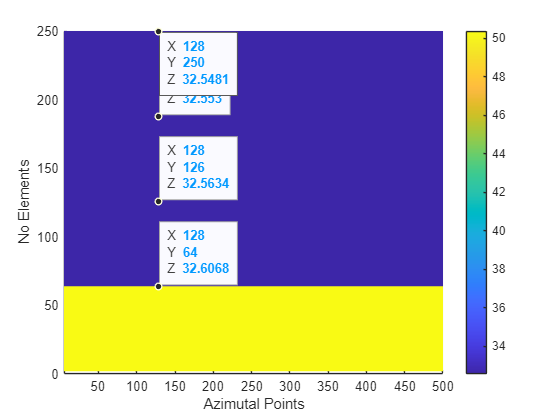


blade_integrator = 'Trapezoidal'; % 'Boole'; 'Rectangle'; 'Simpson';

for c = 1:length(azimutal_points_vec)
    for b = 1:length(No_elements_vec)
        azimutal_points = azimutal_points_vec(c);
        No_elements = No_elements_vec(b);
        sim_init_rotor_simulation
        [F_rotor, T_rotor, rotor_distribution_data] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
        f_vec(c, b) = F_rotor(3);

        clear SIM VEHICLE ROTOR BLADE ATMOSPHERE

    end
end
e_vec = (abs(f_vec - T)./T) * 100;

figure;
[X, Y] = meshgrid(azimutal_points_vec, No_elements_vec);
surf(X, Y, e_vec', 'EdgeColor', 'none');
colorbar;
clim([min(e_vec(:)), max(e_vec(:))]);
xlim([min(azimutal_points_vec), max(azimutal_points_vec)])
xlabel('Azimutal Points');
ylabel('No Elements');
zlabel('Erro relativo (%)');
view(2);